# Interpolación entre matrices de transforación homogéneas

Creamos dos matrices de transformación homogneas a partir de dos orientaciones y dos posiciones. Especificamos el vector de tiempo para la interpolación.

t0 = axang2tform([0 1 1 pi/4])*trvec2tform([0 0 0]);
tF = axang2tform([1 0 1 6*pi/5])*trvec2tform([1 1 1]);
tInterval = [0 1];
tvec = 0:0.01:1;

Interpolamos entre puntos utilizando la función [transformtraj](https://es.mathworks.com/help/robotics/ref/transformtraj.html?searchHighlight=transformtraj&s_tid=srchtitle_transformtraj_1) y graficamos las translaciones.

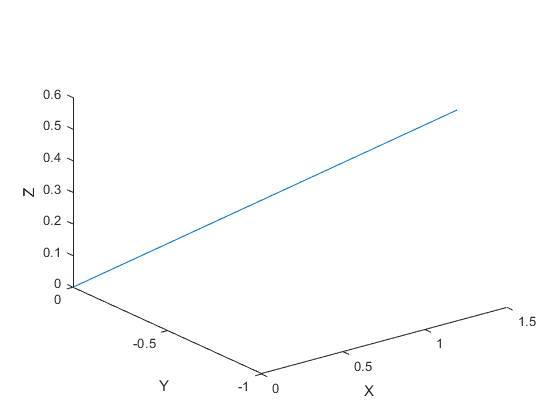

[tfInterp, v1, a1] = transformtraj(t0,tF,tInterval,tvec);
rotations = tform2quat(tfInterp);   %rotaciones especificadas en cuaternios
translations = tform2trvec(tfInterp); 
plot3 (translations (:,1), translations (:,2), translations (:,3));
xlabel('X')
ylabel('Y')
zlabel('Z')

Con la función [plotTransforms](https://es.mathworks.com/help/uav/ref/plottransforms.html?searchHighlight=plotTransform&s_tid=srchtitle_plotTransform_1#description) podemos graficar translaciones y rotaciones.

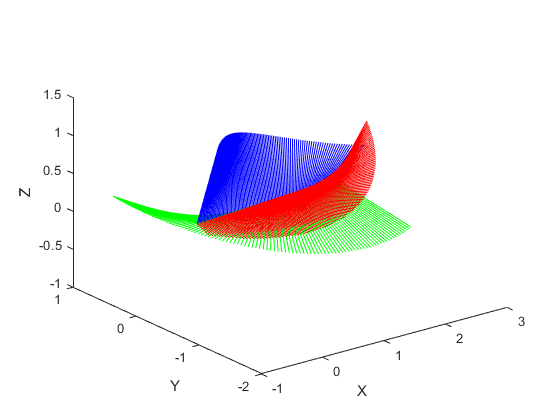

plotTransforms(translations,rotations)
xlabel('X')
ylabel('Y')
zlabel('Z')

# Cálculo de trayectorias de tipo B-Spline y polinomiales cúbica y de quinto orden

Definimos los puntos de paso de la trayecotria y los tiempos.

pts = [0 80 120 90 -20 -10; -20 0 20 35 -20 55]; %waypoints [x; y]
tIni = 0;
tFin = 5;
tStep = 0.1;
tInterval = [tIni tFin];                       %timepoints
tPoints = tIni:tFin;
tvec = tIni:tStep:tFin;

## **Trayectoria B-Spine**

La función [bsplinepolytraj](https://es.mathworks.com/help/robotics/ref/bsplinepolytraj.html) calcula la trayectoria de tipo B-Spline cúbica por tramos que cae en el polígono de control definido por puntos. La trayectoria se genera uniformemente entre los tiempo de inicio y final definidos. Proporciona como salida las posiciones (`q`), velociddad (`qd`), acceleración (`qdd`) y coeficientes del polinomio de la trayectoria calculada.

[qB, qdB, qddB, ppB] = bsplinepolytraj(pts,tInterval,tvec);

## Trayectoria cúbica

`La `función [cubicpolytraj](https://es.mathworks.com/help/robotics/ref/cubicpolytraj.html?searchHighlight=cubicpolytraj&s_tid=srchtitle_cubicpolytraj_1) calcula una trayectoria cúbica y proporciona como salida las posiciones (`q`), velociddad (`qd`), acceleración (`qdd`) y coeficientes del polinomio de la trayectoria calculada.

[qC, qdC, qddC, ppC] = cubicpolytraj(pts, tPoints, tvec);

## Trayectoria de orden 5

La función [`quinticpolytraj`](docid:robotics_ref.mw_e126a472-347c-4b6f-9c00-b593b7c66124) calcula la trayectoria polinomial de 5 orden y proporciona como salida las posiciones (`q`), velociddad (`qd`), acceleración (`qdd`) y coeficientes del polinomio de la trayectoria calculada.

[qQ, qdQ, qddQ, ppQ] = quinticpolytraj(pts, tPoints, tvec);

## Trayectoria con perfil de velocidad trapezoidal

La función [trapveltraj](https://es.mathworks.com/help/robotics/ref/trapveltraj.html?searchHighlight=trapveltraj&s_tid=srchtitle_trapveltraj_1) genera una trayecotria utilizando perfiles de velocidad trapezoidales. Los parámetros de entrada son los puntos intermedios y el número de muestras y proporciona como salidas las posiciones (`q`), velociddad (`qd`), acceleración (`qdd`), vector de tiempo (`tvec`) y coeficientes del polinomio de la trayectoria calculada.

[qT, qdT, qddT, tvec, pp] = trapveltraj(pts, length (tvec));

Más información sobre generación de trayectorias utilizando perfiles de velocidad trapezoidal con límites de velocidad en el siguiente enlace:

[https://es.mathworks.com/help/robotics/ug/design-a-trajectory-with-velocity-limits-using-a-trapezoidal-velocity-profile.html?searchHighlight=trapveltraj&s_tid=srchtitle_trapveltraj_3](https://es.mathworks.com/help/robotics/ug/design-a-trajectory-with-velocity-limits-using-a-trapezoidal-velocity-profile.html?searchHighlight=trapveltraj&s_tid=srchtitle_trapveltraj_3)

Todas estas funciones tienen argumentos de entrada opcionales que permiten definir parámetros relacionados con la velocidad (velocidad máxima) y aceleración.

## Graficar los resultados

Graficar las posiciones XY.

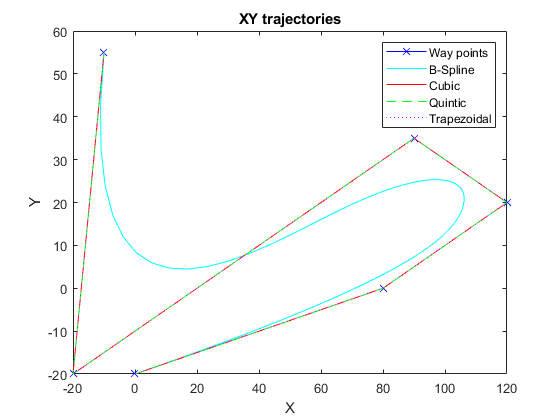

figure
plot(pts(1,:), pts(2,:),'xb-')
hold all
plot(qB(1,:), qB(2,:), 'Color', 'c')
plot(qC(1,:), qC(2,:), 'Color', 'r')
plot(qQ(1,:), qQ(2,:), 'Color', 'g',"LineStyle",'--')
plot(qT(1,:), qT(2,:), 'Color', 'm',"LineStyle",':')
xlabel('X')
ylabel('Y')
legend ('Way points', 'B-Spline', 'Cubic', 'Quintic', 'Trapezoidal')
title ('XY trajectories')
hold off

Graficar posiciones respecto al tiempo

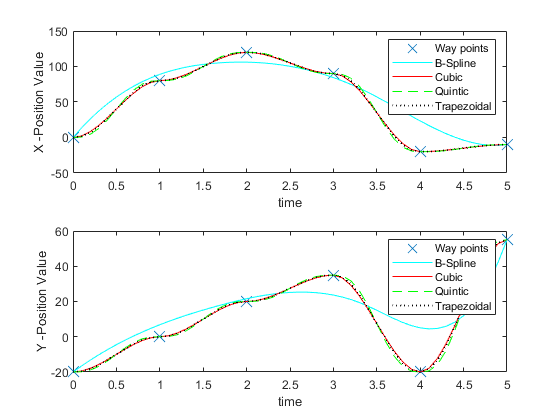

figure
subplot (2,1,1)
plot([0:length(pts)-1],pts(1,:),'x', "MarkerSize", 10)
hold all
plot(tvec,qB(1,:), 'Color', 'c');
plot(tvec,qC(1,:), 'Color', 'r');
plot(tvec,qQ(1,:), 'Color', 'g',"LineStyle",'--')
plot(tvec,qT(1,:), 'Color', 'k',"LineStyle",':', 'LineWidth', 1.25)
xlabel('time')
ylabel('X -Position Value')
legend ('Way points', 'B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off
subplot (2,1,2)
plot([0:length(pts)-1],pts(2,:),'x', "MarkerSize", 10)
hold all
plot(tvec,qB(2,:), 'Color', 'c');
plot(tvec,qC(2,:), 'Color', 'r');
plot(tvec,qQ(2,:), 'Color', 'g',"LineStyle",'--')
plot(tvec,qT(2,:), 'Color', 'k',"LineStyle",':', 'LineWidth', 1.25)
xlabel('time')
ylabel('Y -Position Value')
legend ('Way points', 'B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off

Graficar velocidades respecto al tiempo

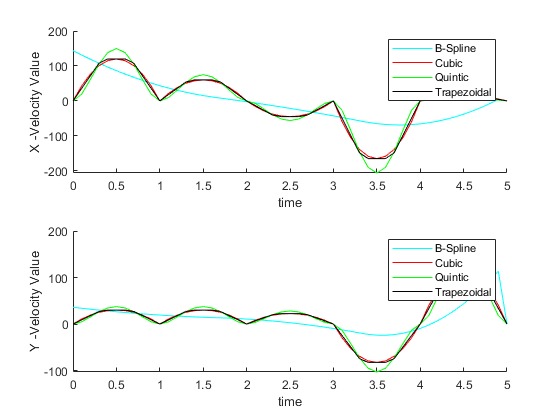

figure
subplot (2,1,1)
hold all
plot(tvec,qdB(1,:), 'Color', 'c');
plot(tvec,qdC(1,:), 'Color', 'r');
plot(tvec,qdQ(1,:), 'Color', 'g')
plot(tvec,qdT(1,:), 'Color', 'k')
xlabel('time')
ylabel('X -Velocity Value')
legend ('B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off
subplot (2,1,2)
hold all
plot(tvec,qdB(2,:), 'Color', 'c');
plot(tvec,qdC(2,:), 'Color', 'r');
plot(tvec,qdQ(2,:), 'Color', 'g')
plot(tvec,qdT(2,:),  'Color', 'k')
xlabel('time')
ylabel('Y -Velocity Value')
legend ('B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off

Graficar aceleración respecto al tiempo

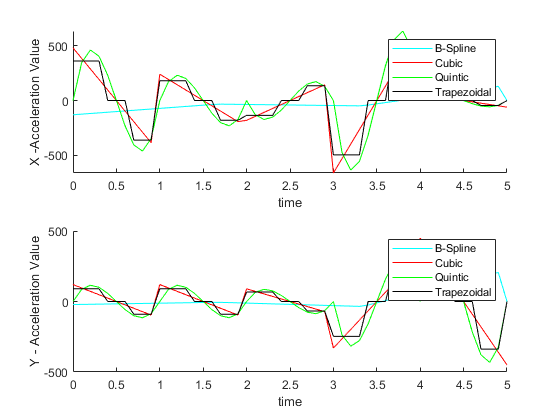

figure
subplot (2,1,1)
hold all
plot(tvec,qddB(1,:), 'Color', 'c');
plot(tvec,qddC(1,:), 'Color', 'r');
plot(tvec,qddQ(1,:), 'Color', 'g')
plot(tvec,qddT(1,:),  'Color', 'k')
xlabel('time')
ylabel('X -Acceleration Value')
legend ('B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off
subplot (2,1,2)
hold all
plot(tvec,qddB(2,:), 'Color', 'c');
plot(tvec,qddC(2,:), 'Color', 'r');
plot(tvec,qddQ(2,:), 'Color', 'g')
plot(tvec,qddT(2,:),  'Color', 'k')
xlabel('time')
ylabel('Y - Acceleration Value')
legend ('B-Spline','Cubic', 'Quintic','Trapezoidal')
hold off